# Opgave 1: Gram-Schmidt

% Oefening 1
A = [1 2 3; 4 5 6; 7 8 9];
[Q,R] = klGS(A);
Q*R

ans =      1     2     3
     4     5     6
     7     8     9


[Q,R] = modGS(A);
Q*R

ans =      1     2     3
     4     5     6
     7     8     9


[Q,R] = herGS(A);
Q*R

ans =      1     2     3
     4     5     6
     7     8     9


% Oefening 3
m = 200;
n = 100;

B = randn(m,n)

B =    -0.5865   -0.6392   -0.2163    0.3998    0.4256   -0.5567   -0.1177   -0.2908   -0.5805    0.4016    0.3618   -0.8344    0.8566    0.2857    0.2864    0.0581   -1.3666    1.2609    1.1909    0.2853    1.3183    1.0144   -0.3956    0.1026    0.7002   -0.5458   -0.4998   -0.0280    1.0908    0.2059   -0.1129   -0.4451    1.4063    0.0452    0.7751    0.8553   -1.7822    0.3918    0.3795    0.8529    1.5427    1.0938    0.7758    1.5512   -1.4977    0.7717   -0.4684    0.5264    0.4048    0.1057
   -0.4285    0.7597   -0.2133    1.1048   -0.6611    0.1810    0.9502    1.0014   -0.6832   -0.8078   -1.0902    0.5102    0.7906   -0.2501   -0.3106    2.0915    0.3040   -0.1405    1.6373   -0.2996    1.2898   -1.3612   -0.6036    0.4084    0.1430   -0.0939    0.9108    0.8534   -0.5167   -0.8937    0.4712   -1.0488    1.7766    0.1822    1.7956   -1.6967   -0.0598   -1.1321   -0.8265   -0.1464    0.3198    1.3698   -1.9517   -0.2391   -0.7374   -0.5943    0.6203    0.7136   -1.3905    0

[Q,~] = qr(B) % sla enkel Q op

Q =    -0.0430    0.0434    0.0191   -0.0265    0.0392    0.0294    0.0107    0.0235    0.0439   -0.0324   -0.0228    0.0605    0.0714   -0.0036    0.0366    0.0024    0.1050   -0.1146   -0.1356    0.0215   -0.0789    0.0606    0.0300   -0.0019    0.0320    0.0295    0.0386   -0.0217    0.0728    0.0597    0.0104    0.0482    0.0791   -0.0156    0.0445   -0.0620   -0.0663   -0.0393    0.0014    0.0721    0.1082    0.0702    0.0571   -0.1230    0.0939   -0.0470   -0.0965    0.0746    0.0325   -0.0344
   -0.0314   -0.0540    0.0232   -0.0951   -0.0303   -0.0147   -0.0517   -0.0630    0.0496    0.0540    0.0775   -0.0365    0.0595    0.0194   -0.0340    0.1643    0.0095    0.0287   -0.1365   -0.0106   -0.1037   -0.1180    0.0662   -0.0480    0.0314    0.0128   -0.0725   -0.0410   -0.0097   -0.0444   -0.0283    0.0658    0.1503    0.0208    0.0373    0.1226   -0.0128    0.0637   -0.0254   -0.0206    0.0051    0.0755   -0.1338   -0.0085    0.0555   -0.0074    0.0355    0.0541   -0.0911   -0

size(Q)

ans =    200   200



D = eye(m,m);
for i = 1:m
    D(:,i) = D(:,i) * 2^(1-i);
end
size(D)

ans =    200   200



V = eye(m,m);
V(1,:) = 1;
size(V)

ans =    200   200



A = Q*D*V

A =    -0.0430   -0.0213   -0.0382   -0.0463   -0.0405   -0.0420   -0.0428   -0.0428   -0.0428   -0.0430   -0.0430   -0.0429   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430
   -0.0314   -0.0584   -0.0256   -0.0433   -0.0333   -0.0319   -0.0322   -0.0319   -0.0312   -0.0313   -0.0313   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0


C = zeros(m,m);
C(:,1) = Q(:,1);
for j = 2:m
    C(:,j) = Q(:,1) + 2^(1-j)*Q(:,j);
end
disp(C)

  Columns 1 through 23

   -0.0430   -0.0213   -0.0382   -0.0463   -0.0405   -0.0420   -0.0428   -0.0428   -0.0428   -0.0430   -0.0430   -0.0429   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430   -0.0430
   -0.0314   -0.0584   -0.0256   -0.0433   -0.0333   -0.0319   -0.0322   -0.0319   -0.0312   -0.0313   -0.0313   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314   -0.0314
   -0.0068    0.0123   -0.0235   -0.0396   -0.0131   -0.0097   -0.0084   -0.0070   -0.0069   -0.0072   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068
   -0.0252   -0.0161   -0.0253   -0.0364   -0.0291   -0.0230   -0.0245   -0.0258   -0.0253   -0.0253   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252   -0.0252
   -0.0604   -0.0601   -0.0828   -0.0656   -0.0611  


% Oefening 4
[Q1,~] = klGS(A)

Q1 =    -0.0430    0.0434    0.0191   -0.0265    0.0392    0.0294    0.0107    0.0235    0.0439   -0.0324   -0.0228    0.0605    0.0714   -0.0036    0.0366    0.0024    0.1050   -0.1146   -0.1356    0.0215   -0.0789    0.0606    0.0301   -0.0019    0.0321    0.0297    0.0352   -0.0373    0.0131   -0.0057   -0.0158   -0.0149   -0.0151   -0.0158   -0.0157   -0.0158   -0.0158   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157
   -0.0314   -0.0540    0.0232   -0.0951   -0.0303   -0.0147   -0.0517   -0.0630    0.0496    0.0540    0.0775   -0.0365    0.0595    0.0194   -0.0340    0.1643    0.0095    0.0287   -0.1365   -0.0106   -0.1037   -0.1180    0.0660   -0.0485    0.0293    0.0088   -0.0807   -0.0270    0.0017   -0.0043    0.0010    0.0053    0.0056    0.0045    0.0045    0.0045    0.0044    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    

Q2 =    -0.0430    0.0434    0.0191   -0.0265    0.0392    0.0294    0.0107    0.0235    0.0439   -0.0324   -0.0228    0.0605    0.0714   -0.0036    0.0366    0.0024    0.1050   -0.1146   -0.1356    0.0215   -0.0789    0.0606    0.0300   -0.0019    0.0320    0.0295    0.0386   -0.0217    0.0728    0.0597    0.0104    0.0482    0.0791   -0.0156    0.0445   -0.0620   -0.0663   -0.0393    0.0014    0.0721    0.1082    0.0703    0.0571   -0.1230    0.0940   -0.0468   -0.0967    0.0751    0.0327   -0.0365
   -0.0314   -0.0540    0.0232   -0.0951   -0.0303   -0.0147   -0.0517   -0.0630    0.0496    0.0540    0.0775   -0.0365    0.0595    0.0194   -0.0340    0.1643    0.0095    0.0287   -0.1365   -0.0106   -0.1037   -0.1180    0.0662   -0.0480    0.0314    0.0128   -0.0725   -0.0410   -0.0097   -0.0444   -0.0283    0.0658    0.1503    0.0208    0.0373    0.1226   -0.0128    0.0637   -0.0254   -0.0206    0.0051    0.0755   -0.1338   -0.0085    0.0556   -0.0073    0.0354    0.0547   -0.0918   -

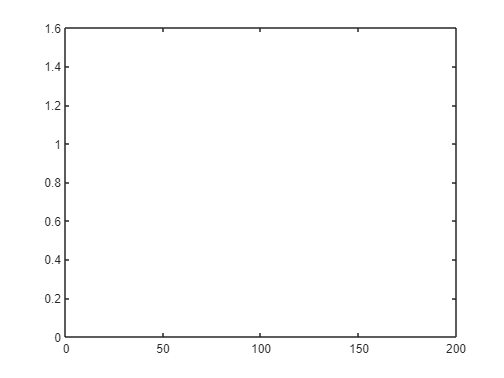

[Q2,~] = modGS(A)